# Get Started with ROS

This example introduces how to set up ROS within MATLAB®, and get information about ROS network (topics, services, and messages) through command line helper functions. 

Robot Operating System (ROS) is a communication interface that enables different parts of a robot system to discover each other, and send and receive data between them. MATLAB® supports ROS with a library of functions that enables you to exchange data with ROS-enabled physical robots or robot simulators such as Gazebo®.

## ROS Terminology

- A *ROS network* comprises different parts of a robot system (such as a planner or a camera interface) that communicate over ROS. The network can be distributed over several machines.

- A *ROS master* coordinates the different parts of a ROS network. It is identified by a *Master URI* (Uniform Resource Identifier) that specifies the hostname or IP address of the machine where the master is running.

- A *ROS node *contains a collection of related ROS capabilities (such as publishers, subscribers, and services). A ROS network can have many ROS nodes.

- *Publishers*, *subscribers*, and *services* are different kinds of ROS entities that process data. They exchange data using *messages*.

- A publisher sends messages to a specific *topic* (such as "odometry"), and subscribers to that topic receive those messages. A single topic can be associated with multiple publishers and subscribers.

For more information, see [Robot Operating System (ROS)](docid:ros_gs.mw_79ccfff3-bdbd-46d8-899f-e5add5a50fad) and the [Concepts](https://wiki.ros.org/ROS/Concepts) section on the ROS website.

## ROS Path

All of the ROS code that we will be adding will be contained within a new folder. This folder will have an increasing number of sub-folders.

Remember that in order for this code to work in matlab, you will need to "Add with subfolders". Remember to do this in future weeks if new subfolders are added.

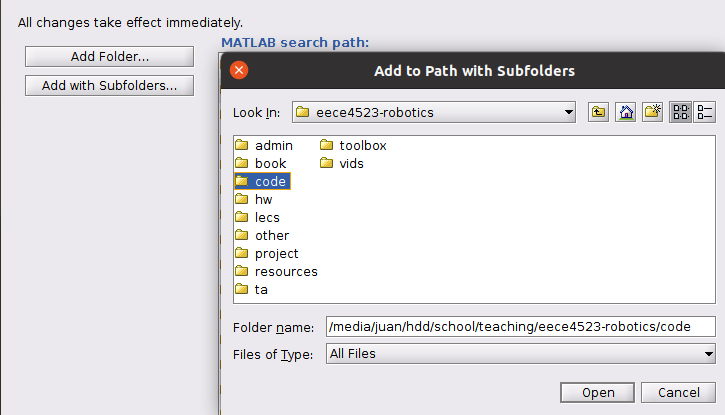

## Initialize ROS Network

Use [`rosinit`](docid:ros_ref.bupf5_j_1) to initialize ROS (without connecting to an external host like Gazebo). 

By default, `rosinit` creates a *ROS master* in MATLAB and starts a *global node* that is connected to the master. The global node is automatically used by other ROS functions. 

rosinit

Launching ROS Core...
Done in 0.40057 seconds.
Initializing ROS master on http://10.51.75.164:11311.
Initializing global node /matlab_global_node_50551 with NodeURI http://toro.bisonnet.lipscomb.edu:44303/ and MasterURI http://localhost:11311.


Use [`rosnode`](docid:ros_ref.bupf5_j_4)` list` to see all nodes in the ROS network. Note that the only available node is the global node created by `rosinit`.

rosnode list

The following code, will create a toy example setting up a fake robot with different nodes. 

Use `exampleHelperROSCreateSampleNetwork` to populate the ROS network with three additional nodes and sample publishers and subscribers.

exampleHelperROSCreateSampleNetwork

This code should be available from our github repository, however, if for any reason you cannot open it, the original would be found in the following link: [https://www.mathworks.com/help/ros/ug/get-started-with-ros.html](https://www.mathworks.com/help/ros/ug/get-started-with-ros.html) 

Use `rosnode list` again to see the three new nodes (`node_1`, `node_2`, and `node_3`).

rosnode list

The figure shows the current state of the ROS network. The MATLAB global node is disconnected since it currently does not have any publishers, subscribers or services.

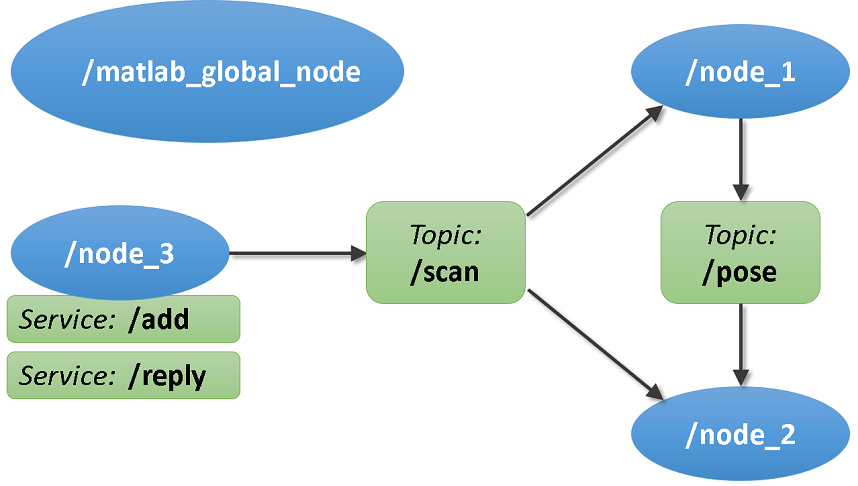

## Topics

Use [`rostopic`](docid:ros_ref.bupf5_j_14)` list` to see available topics in the ROS network. There are four active topics: `/pose`, `/rosout`, `/scan` and `/tf`. The default topics: `rosout` and `tf` are always present in the ROS network. The other two topics were created as part of the sample network.

rostopic list

Use `rostopic info ``<topicname>` to get specific information about a specific topic. The command below shows that `/node_1` publishes (sends messages to) the `/pose` topic, and `/node_2` subscribes (receives messages from) to that topic. See [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_fa34dc6f-351e-4ab5-8680-46563496814b) for more information.

rostopic info /pose

Use [`rosnode`](docid:ros_ref.bupf5_j_4)` info ``<nodename>` to get information about a specific node. The command below shows that `node_1` publishes to `/pose`, `/rosout` and `/tf` topics, subscribes to the `/scan` topic and provides services: /node_1/get_loggers and /node_1/set_logger_level. The default logging services: get_loggers and set_logger_level are provided by all the nodes created in ROS network.

rosnode info /node_1

## Services

ROS services provide a mechanism for procedure calls across the ROS network. 

A *service client* sends a request message to a *service server*, which processes the information in the request and returns with a response message (see [Call and Provide ROS Services](docid:ros_ug.mw_70dbf089-5821-4e67-b96f-f659aea10c0c)). Services will be things we do once. Ask the simulation to reset, change physics parameters, or retrieve a one-time data from the robot: cameras, gripper, etc.

Use [`rosservice`](docid:ros_ref.bupf5_j_7)` list` to see all available service servers in the ROS network. 

The command below shows that two services (`/add` and `/reply`) are available along with the default logger services of all the nodes.

rosservice list

Use `rosservice info ``<servicename>` to get information about a specific service.

rosservice info /add

## Messages

Publishers, subscribers, and services use ROS messages to exchange information. 

Each ROS message has an associated *message type* that defines the datatypes and layout of information in that message (See [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36)).

Use [`rostopic`](docid:ros_ref.bupf5_j_14)` type ``<topicname>` to see the message type used by a topic. The command below shows that the `/pose` topic uses messages of type `geometry_msgs/Twist`.

rostopic type /pose

geometry_msgs/Pose


Use [`rosmsg`](docid:ros_ref.bupf5_j_3)` show ``<messagetype>` to view the properties of a message type. 

The `geometry_msgs/Twist` message type has two properties, `Linear` and `Angular`. 

rosmsg show geometry_msgs/Twist

% This expresses velocity in free space broken into its Linear and Angular parts.
Vector3  Linear
Vector3  Angular



Each property is a message of type `geometry_msgs/Vector3`, which in turn has three properties of type `double`.

rosmsg show geometry_msgs/Vector3

% This represents a vector in free space. 
% It is only meant to represent a direction. Therefore, it does not
% make sense to apply a translation to it (e.g., when applying a 
% generic rigid transformation to a Vector3, tf2 will only apply the
% rotation). If you want your data to be translatable too, use the
% geometry_msgs/Point message instead.

double X
double Y
double Z


Use `rosmsg list` to see the full list of message types available in MATLAB.

## Shut Down ROS Network

Use `exampleHelperROSShutDownSampleNetwork` to remove the sample nodes, publishers, and subscribers from the ROS network. 

This command is only needed if the sample network was created earlier using `exampleHelperROSStartSampleNetwork`.

exampleHelperROSShutDownSampleNetwork

Use [`rosshutdown`](docid:ros_ref.bupf5_j_8) to shut down the ROS network in MATLAB. 

This shuts down the ROS master that was started by [`rosinit`](docid:ros_ref.bupf5_j_1) and deletes the global node. Using `rosshutdown` is the recommended procedure once you are done working with the ROS network.

rosshutdown

## Interacting with Gazebo

The previous example was for a toy situation, we can retry doing the same thing with Gazebo.

Recalling the ip address of your virtual machine and that of your host call rosinit and replace them with your own ip addresses:

rosinit("10.51.79.165", 11311, "NodeHost","10.51.70.245");

Initializing global node /matlab_global_node_35315 with NodeURI http://10.51.70.245:46321/ and MasterURI http://10.51.79.165:11311.


## Simulation Nodes

Let's see what nodes exist in the simulation:

rosnode list

As you will see, there are a number of them:

- matlab_global_node is the node that keeps tabs of everything in the network.

- gazebo is the node that spawns everythin in the simulation.

- robot_state_publisher takes joint information from the robot and creates a list of poses across any two coordinate frames in the world. This is called a **tftree**.

## The Gazebo Node

Let's learn more about what the Gazebo node does:

rosnode info /gazebo

Gazebo is a mamoth node. It publishes 24 different topics (camera, force-torque sensor, gripper, and trajectory generation actions), subsribes to 10 (controller commands for joints and gripper -- i.e. goals) and gazebo simulation link and model states); there are also 40 services that allows us to change controller types, apply manual forces in the simulation, along with other simulation manipulations)

## Simulation Topics

We can study individual ROS topics. List them first using **rostopic list:**

rostopic list

A key topic you will use a lot at the beginning is the **/joint_poses** topic. This topic will include the name of all the joints in the robot as well as the values of each of the joints in radians. 

We can extract information using **rostopic info topicname**. For example, what node published this topic? What node subscribed to this topic?

rostopic info /joint_states

We can learn the type of this topic using **rostopic type topicname**? Is it just an int? a double? A complicated structure?

rostopic type /joint_states

Seeing a type of **sensor_msgs/JointState** is not very useful. If we wanted to know what this data type looks like exactly, we can use **rosmsg show type:**

rosmsg show sensor_msgs/JointState

The structure is complicated. It starts with:

- a header, which is in itself another structure

- vectors of chars/strings for joint names

- vectors of double for position, velocity, and effort. 

Could we extract the data in real time to see this structure? Yes. Run the following command in your command window instead of the live notebook:

rostopic echo /joint_states

Note how Header contains a time marker called Stamp (which is itself a compound structure), along with a counter Seq and the name of the parent coordinate frame if appropriate:

- Header

-     Stamp:

-         Secs - seconds

-         Nsecs - nanoseconds

-     Seq - a simple counter

-     FrameId - the name of the parent frame in the simulation if appropriate

After the header we have 4 vectors called Name, Position, Velocity, Effort. 

- Name will publish the robot's joint names **out of order: **

-     elbow_joint

-     robotiq_85_left_knuckle_joint (i.e. the left finger joint)

-     shoulder_lift_joint

-     should_pan_joint

-     wrist_1_joint

-     wrist_2_joint

-     wrist_3_joint

- Position will have the corresponding joint angles for those according to their name.

Some of these quantities may not change. For example, we are currently not collecting Effort information, which is an alias for force or torque information depending if we are using prismatic or revolute joints. 

## Shutdown

We have concluded our tutorial. You can shutdown the rosnetwork before you leave:

rosshutdown

## Summary

This notebook has now introduced how to connect to ROS in the VM and how to examine the nodes, topics, and messages running therein. We will now continue to learn more about nodes, topics, publishers, and subscribers.